#     Electromagnetic Analysis of Intelligent Reflecting Surface

clear all;
close all;
clc;

This example shows how to model the response of an intelligent reflecting surface (IRS) using full-wave electromagnetic simulation. The IRS, also known as the reconfigurable intelligent surface (RIS), large intelligent surface (LIS), or metasurface, has garnered significant interest in the wireless communication community. The IRS consists of a large array of subwavelength unit cell elements which can manipulate the phase, amplitude, polarization, or frequency of the incident signal. If an obstacle blocks the direct path between the base station (BS) and the user equipment (UE), the parasitic reflection of the IRS can provide an alternative path for signal transmission, as this figure shows. An external phase control mechanism can be integrated to control the reflection characteristics of the IRS.

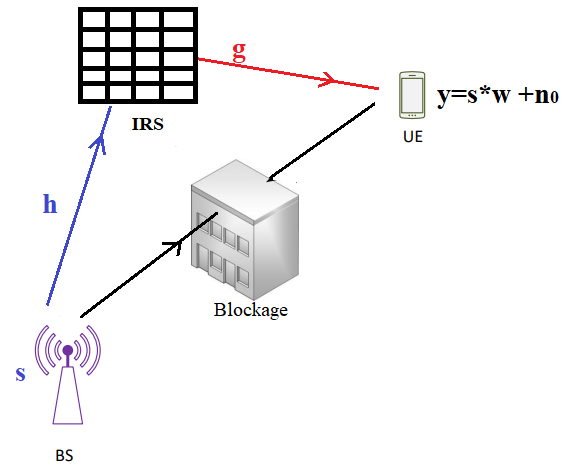

The inclusion of the RIS provides a two-segment indirect path to the signal traveling between the BS and the UE. The first segment covers the path between the BS and the IRS. The second segment covers the path between the IRS and the UE. The channel matrix of these two signal paths depends on the geometry and the electromagnetic reflection properties of the IRS.

The signal received at the UE is represented mathematically in [1] using this equation.

$r=sw+n_0=s\frac{\sqrt{G_rG_uG_tA_rA_u}}{4\pi}\sum_{n=1}^N \frac{\sqrt{\tilde{F}_n}R}{d_{tn}d_{rn}}e^\frac{-j2\pi(d_{tn}+d_{rn})}{\lambda}+n_0$,

where

- 
$$R=[R_1~R_2~......R_n]^T.$$


- $G_u$ is the embedded gain of the $n^{th}$ IRS element.

- $G_t$ is the embedded gain of the BS transmitter.

- $G_r$ is the embedded gain of the UE receiver.

- $F_n=F_n^tF_n^rF_{n}^{tx}F^{rx}_n$ is the product of the normalized power patterns of the BS, UE, and IRS.

- $d_t$ is the distance between the BS and the $n^{th}$ IRS element.

- $d_r$ is the distance between the UE and the $n^{th}$ IRS element.

- $A_r$ is the  effective aperture area of the UE.

- $A_u$ is the effective aperture area of the $n^{th}$ IRS element.

- $\lambda$ is the free-space wavelength.

For this example, assume that the IRS has $$N$$ unit cell elements. The complex reflection coefficient of the $n^{th}$ IRS element is denoted by $R_n=R^{mag}_n e^{j\tau_n}$.

The reflection coefficients of the IRS depend on these factors:

- Direction and polarization of the incoming signal towards the IRS.

- Direction and polarization of the outgoing signal from the IRS.

- Material properties and geometry of the IRS.

This example focuses on varying the incident signal configurations and determining the corresponding reflection characteristics.

Assume that $d_{tn}$ and $d_{rn}$ are in the far-field range. You can abstract the IRS as [infiniteArray](docid:antenna_ref#bvfg_q0-1) catalog element with a [planeWaveExcitation](docid:antenna_ref#bvj2_xq-1) model.

### Parameters

#### IRS

pos_IRS=[0, 0, 2]; % location of the IRS
F0 = 28e9; %operational frequency
lambda = physconst("LightSpeed")/F0;N_v=25; %Number of rows of reflecting units on the RIS
N_h=25; %Number of columns of reflecting units on the RIS
Gu_dBi = 9.03; % gain of reflecting unit see [2] and [1,Sec. IV and Table I]
Gu = 10^(Gu_dBi/10); %gain of reflecting unit in the linear scale

D_h=lambda/2;
IRS_size=D_h*N_v;

#### Transmitter, see parameters in [1,Sec. IV and Table I]

Gt_dBi=21; %gain of the transmit antenna in dBi
Gt = 10^(Gt_dBi/10); %gain of the transmit antenna in the linear scale
F_tx=ones(N_v,N_h);% radiation patern of the transmit antenna
pos_tx=[5,-5,2];
%k = 2*pi/lambda;

Incident wave Calculation

inc_loc=pos_tx-pos_IRS;%location of the incident wave relative to the IRS position
[phi_inc,theta_inc,radius_inc]=cart2sph(inc_loc(1),inc_loc(2),inc_loc(3));
elevation_inc = pi/2 + theta_inc; % rotate the emitter
%transforming from rad to degrees
phi_inc=rad2deg(phi_inc);
theta_inc=rad2deg(theta_inc);

% phi_inc = -45:10:45;
% theta_inc = -45:10:45;
% elevation_inc = 90 + theta_inc;
% radius_inc = 100*lambda;
% [x_inc,y_inc,z_inc] = sph2cart(phi_inc*pi/180,elevation_inc*pi/180,radius_inc);
% inc_loc = [x_inc' y_inc' z_inc'];

#### Receiver, see parameters in [1,Sec. IV and Table I]

Gr_dBi=21; %gain of the receiver antenna
Gr = 10^(Gr_dBi/10); %gain of the receive antenna in the linear scale
F_rx=ones(N_v,N_h);% radiation patern of the receive antenna
A_r= lambda^2/4/pi;
pos_rx=[5,2,0];
%k = 2*pi/lambda;


#### Fontsize

fontsize=15;

## Configuring the IRS

#### Specify the observation location for Reflected Wave

Set the location of observation in the far-field region by specifying arbitrary azimuth angle, elevation angle, and radial distance values. Compute the receiving location in the Cartesian coordinate system.

phi_obs_IRS = 45;
theta_obs_IRS = 20;
elevation_obs_IRS = 90 - theta_obs_IRS;
radius_obs_IRS = norm(pos_rx-pos_IRS);

#### Create and Visualize Geometry of Unit Cell

Design a reflector-backed dipole antenna at the operation frequency `F0` using the [reflector](docid:antenna_ref#bvclvwc-1) and [dipole](docid:antenna_ref#bvbbmax-1) objects. Tilt the dipole to make it horizontal to the ground plane. Visualize the reflector element using the `show` function. The ground plane length and reflector width determine the periodicity of the IRS.

rf = design(reflector,F0);
rf.Spacing = lambda/10;
rf.GroundPlaneLength = 0.5*lambda;
rf.GroundPlaneWidth = 0.5*lambda;
% figure;
% show(rf)

#### Visualize Finite IRS

Create a 10-by-10 finite IRS using the [rectangularArray](docid:antenna_ref#bvcl6lz-1) object and visualize it using the `show` function. Each unit cell element of the periodic IRS comprises a reflector object with a horizontal bowtie antenna as the exciter. 

ifa = rectangularArray(Element=rf, Size=[10 10],...
    ColumnSpacing=rf.GroundPlaneLength,...
    RowSpacing=rf.GroundPlaneWidth);
% figure;
% show(ifa)
% title("Finite IRS")

#### Create and Visualize the Infinite IRS

Commonly, IRS configurations contain a very large number of array elements. Considering the long simulation time of such a large array, infinite array approximation using a periodic Green's function is a suitable alternative. In the [Modelling Mutual Coupling in Large Arrays Using Infinite Array Analysis](docid:antenna_ug#example-ex37130374) example, you design the IRS using an `infiniteArray` object.

Assign the reflector as the unit cell element of the IRS. Specify the scan angles of the IRS based on the receiver direction. The accuracy of infinite array modeling depends on the number of summation terms in the periodic Green's function, which you can se using `numSummationTerms`. Use the `show` function to visualize the IRS.

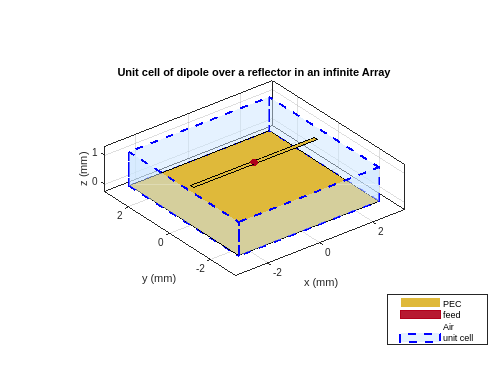

irs = infiniteArray(Element=rf);
irs.ScanAzimuth = phi_obs_IRS;
irs.ScanElevation = elevation_obs_IRS;
numSummationTerms(irs,20);
figure;
show(irs)

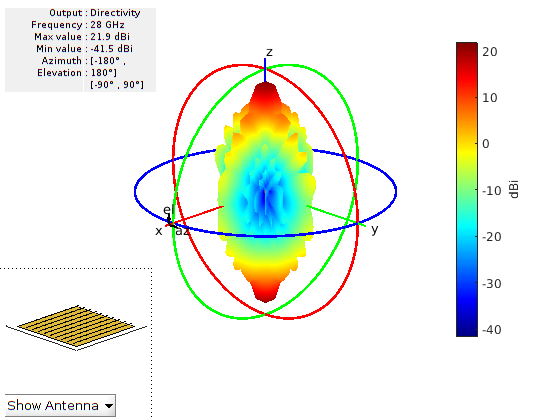

% title("Infinite IRS")
% Compute the Array factor
AF=hArrayFactorCalc(irs,F0);

% Construct a planeWaveExcitation object with the IRS as element
[pw,pol,dir] = hcalcPlaneWaveIncidence(theta_inc,phi_inc,ifa);
figure;
pattern(pw,F0);

#### Exploration vector

Vector that evaluates the exploration location for the IRS

phi_obs = -90:1:90;
theta_obs = -45:1:45;
elevation_obs = 90 - theta_obs;
radius_obs = norm(pos_rx-pos_IRS);%100*lambda;
% [x_obs,y_obs,z_obs] = sph2cart(phi_obs*pi/180,elevation_obs*pi/180,radius_obs);
% obs_loc = [x_obs', y_obs', z_obs'];


#### Depicting the Scenario

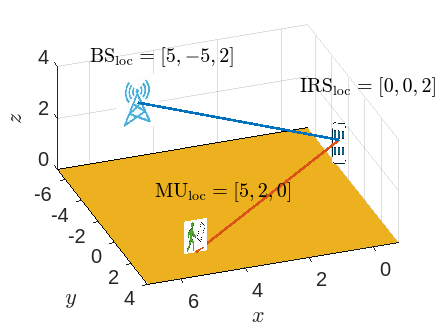

figure;
%depicting the MU
rot_az=20*pi/360;
rx_size=1.7;
img = imread('figures/MU.jpg');
[row,col]=size(img);
xImage = [pos_rx(1)-row/col*rx_size*cos(rot_az) pos_rx(1)+row/col*rx_size*cos(rot_az);...
          pos_rx(1)-row/col*rx_size*cos(rot_az) pos_rx(1)+row/col*rx_size*cos(rot_az)]; % The y data for the image corners

yImage = [pos_rx(2) pos_rx(2);...
          pos_rx(2) pos_rx(2)]; % The x data for the image corners


zImage = [pos_rx(3)+1.5*rx_size/2 pos_rx(3)+1.5*rx_size/2;...
          pos_rx(3) pos_rx(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none'); hold on;
txt=strcat("$$\mathrm{MU}_\mathrm{loc}=[",num2str(pos_rx(1)),",",num2str(pos_rx(2)),",",num2str(pos_rx(3)),"]$");
text(pos_rx(1)+rx_size,pos_rx(2)+rx_size,pos_rx(3)+2*rx_size,txt,'Interpreter','latex','FontSize',fontsize);

%depicting the BS
rot_az=0*pi/360;
% rot_el=30*2*pi/360;
tx_size=2;
img = imread('figures/BS.jpg');
[row,col]=size(img);
xImage = [pos_tx(1)-row/col*tx_size*cos(rot_az) pos_tx(1)+row/col*tx_size*cos(rot_az);...
          pos_tx(1)-row/col*tx_size*cos(rot_az) pos_tx(1)+row/col*tx_size*cos(rot_az)]; % The y data for the image corners
yImage = [pos_tx(2) pos_tx(2);...
          pos_tx(2) pos_tx(2)]; % The x data for the image corners
zImage = [pos_tx(3)+tx_size pos_tx(3)+tx_size;...
          pos_tx(3) pos_tx(3)];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{BS}_\mathrm{loc}=[",num2str(pos_tx(1)),",",num2str(pos_tx(2)),",",num2str(pos_tx(3)),"]$");
text(pos_tx(1)+tx_size,pos_tx(2)+tx_size,pos_tx(3)+2*tx_size,txt,'Interpreter','latex','FontSize',fontsize);

xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

%depicting the IRS
IRS_size=D_h*N_v*2;
IRS_scale=0.5;
rot_az=150*pi/360;
img = imread('figures/IRS.jpg');
xImage = [pos_IRS(1)-row/col*tx_size*cos(rot_az) pos_IRS(1)+row/col*tx_size*cos(rot_az);...
          pos_IRS(1)-row/col*tx_size*cos(rot_az) pos_IRS(1)+row/col*tx_size*cos(rot_az)]; % The X data for the image corners

yImage = [pos_IRS(2)+IRS_scale*IRS_size pos_IRS(2)-IRS_scale*IRS_size;...
          pos_IRS(2)+IRS_scale*IRS_size pos_IRS(2)-IRS_scale*IRS_size]; % The Y data for the image corners


zImage = [pos_IRS(3)+3*IRS_scale*col/row*IRS_size pos_IRS(3)+3*IRS_scale*col/row*IRS_size;...
          pos_IRS(3)-1*IRS_scale*col/row*IRS_size pos_IRS(3)-1*IRS_scale*col/row*IRS_size];   % The z data for the image corners
surf(xImage,yImage,zImage,...    % Plot the surface
     'CData',img,...
     'FaceColor','texturemap','EdgeColor','none');
txt=strcat("$\mathrm{IRS}_\mathrm{loc}=[",num2str(pos_IRS(1)),",",num2str(pos_IRS(2)),",",num2str(pos_IRS(3)),"]$");
text(pos_IRS(1)+2*IRS_size,pos_IRS(2)-10*IRS_size,pos_IRS(3)+2*IRS_size*col/row,txt,'Interpreter','latex','FontSize',fontsize);

%depicting the line from the BS to the IRS
plot3([pos_tx(1) pos_IRS(1)],[pos_tx(2) pos_IRS(2)], [pos_tx(3)+tx_size/2 pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the line from the IRS to the MU
plot3([pos_rx(1) pos_IRS(1)],[pos_rx(2) pos_IRS(2)], [pos_rx(3) pos_IRS(3)+IRS_size*2],'LineWidth',2);

%depicting the ground plane
rect=rectangle('Position',[min([pos_tx(1),pos_IRS(1),pos_rx(1)])-max([tx_size,IRS_size,rx_size])...
                           min([pos_tx(2),pos_IRS(2),pos_rx(2)])-max([tx_size,IRS_size,rx_size]) ...
                           max([pos_tx(1),pos_IRS(1),pos_rx(1)])-min([pos_tx(1),pos_IRS(1),pos_rx(1)])+2*max([tx_size,IRS_size,rx_size]) ...
                           max([pos_tx(2),pos_IRS(2),pos_rx(2)])-min([pos_tx(2),pos_IRS(2),pos_rx(2)])+2*max([tx_size,IRS_size,rx_size]) ...
                           ],'FaceColor',"#EDB120");


axis([min([pos_tx(1),pos_IRS(1),pos_rx(1)])-3*min([tx_size,IRS_size,rx_size]) ...
      max([pos_tx(1),pos_IRS(1),pos_rx(1)])+max([tx_size,IRS_size,rx_size])...
      min([pos_tx(2),pos_IRS(2),pos_rx(2)])-max([tx_size,IRS_size,rx_size]) ...
      max([pos_tx(2),pos_IRS(2),pos_rx(2)])+max([tx_size,IRS_size,rx_size])...
      min([pos_tx(3),pos_IRS(3),pos_rx(3)]) ...
      max([pos_tx(3),pos_IRS(3),pos_rx(3)])+max([tx_size,IRS_size,rx_size])]);


xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
zlabel('$z$','Interpreter','latex');
set(gca,'FontSize',fontsize);

view([-200 50])

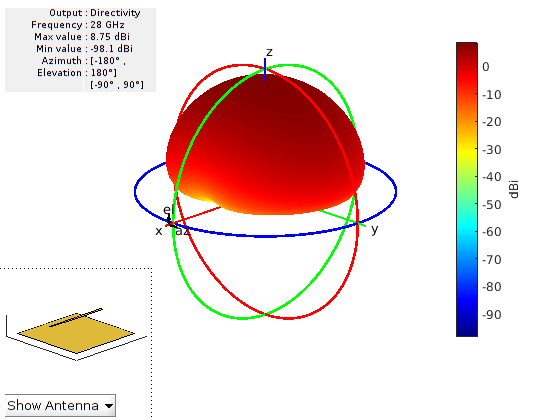

### Evaluate Direction and Polarization to IRS

Initialize the magnitude and phase of the field reflection coefficient for different incident configurations. To excite the IRS, specify it as the `Element` of `planeWaveExcitation` object. Specify the polarization and direction of the incident wave.

Initialize the magnitude and phase of the reflection coefficients. The corresponding matrix stores per row the entry [mag,theta,phi]

MagReflection=zeros(numel(phi_obs)*numel(theta_obs),3);
PhaseReflection=zeros(numel(phi_obs)*numel(theta_obs),3);


Calculate the reflection coefficients for each value of the incidence angles.

k=1;
% Construct a planeWaveExcitation object with the IRS as element
[pw,pol,dir] = hcalcPlaneWaveIncidence(theta_inc,phi_inc,irs);
% Compute incident field upon the IRS
Ein = pol;
Einc = dot(Ein,pol/norm(pol));

for elev = 1:numel(theta_obs)%loop in the elevation direction

    disp(elev/numel(theta_obs)*100)

    for az=1:numel(phi_obs) %loop in the azimuth direction

        % Compute the outward scattered field from the IRS
        [x_obs,y_obs,z_obs] = sph2cart(phi_obs(az)*pi/180,elevation_obs(elev)*pi/180,radius_obs);
        obs_loc = [x_obs, y_obs, z_obs];
        [Eo,~] = EHfields(pw,F0,obs_loc');
        Eo = Eo*AF;
        Eobs = dot(Eo,pol/norm(pol));

        % Compute the reflection coefficient of the IRS
        MagReflection(k,1) = abs(Eobs/Einc);
        MagReflection(k,2) = theta_obs(elev);
        MagReflection(k,3) = phi_obs(az);

        PhaseReflection(k,1) = (angle(Eobs/Einc))*180/pi;
        PhaseReflection(k,2) = theta_obs(elev);
        PhaseReflection(k,3) = phi_obs(az);
        k=k+1;
    end
end

    10

    20

    30

    40

    50

    60

    70

    80

    90

   100




save magreflection_vs_observation_angle MagReflection PhaseReflection F0 lambda irs rf ifa

You can do this analysis by using alternate infinite array configurations and different unit cell element to achieve desired IRS channel matrix behavior. Based on the phase of the reflection coefficients, the signal at the receiver's end can be constructively/destructively interfered to enhance/reduce the received signal strength in a specific observation direction.

## Further Exploration

Using the full-wave electromagnetic solution of Maxwell's equations from Antenna Toolbox™, you can perform a similar analysis with different IRS configurations constructed from the `infiniteArray` and `planeWaveExcitation` objects to design a physics-based smart propagation environment. The geometry of an IRS can be further integrated with Communication Toolbox™ and Optimization Toolbox™ software to obtain an accurate, physics-based characterization of IRS-aided wireless communication scenarios.

## Reference

[1] Cui, Yaoshen, Haifan Yin, Li Tan, and Marco Di Renzo., " A 3D Positioning-based Channel Estimation Method for RIS-aided mmWave Communications." arXiv:2203.14636 (April 21, 2022). [https://doi.org/10.48550/arXiv.2203.14636](https://doi.org/10.48550/arXiv.2203.14636).

*Copyright 2022 The MathWorks, Inc.*